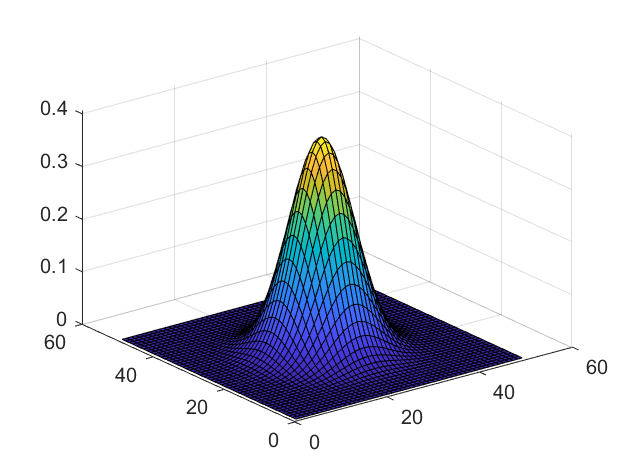

clear all; close all;
k=-0.001;%m2/S
Lx=1;
Nx=50;
Dx=Lx/Nx;
Nt=100;
Dt=0.1;%s
U=zeros(Nx,Nx,Nt);
beta=k*Dt/Dx^2; %betalim=0.5
for i=1:Nx
    for j=1:Nx
        if ((i-Nx/2)^2+(j-Nx/2)^2)*Dx^2<=0.1^2
            U(i,j,1)=1;
        end
    end
end
for n=1:Nt
    for i=2:Nx-1
        for j=2:Nx-1
            U(i,j,n+1)=U(i,j,n)-beta/2*(U(i+1,j,n)+U(i-1,j,n)+U(i,j+1,n)+U(i,j-1,n)-4*U(i,j,n));
        end
    end
    U(1,:,n+1) = 0;
    U(Nx,:,n+1) = 0;
    U(:,1,n+1) = 0;
    U(:,Nx,n+1) = 0;
    if mod(n,10)==0, surf(U(:,:,n)); pause(0.1); end
end

surf(U(:,:,Nt));